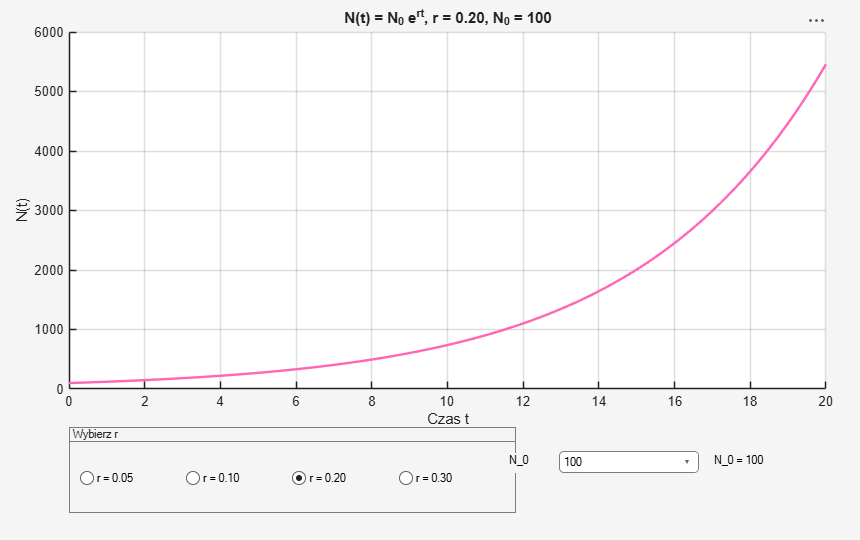

rValues = [0.05 0.10 0.20 0.30];
n0Values = [5 10 25 50 100 250 500 1000];
t = linspace(0, 20, 500);

f = figure('Name', 'Wzrost populacji', 'NumberTitle', 'off', ...
    'Position', [100 100 860 540]);

ax = axes('Parent', f, 'Position', [0.08 0.28 0.88 0.66]);
grid(ax, 'on')
hold(ax, 'on')

r = 0.2;
n0 = 100;
n = n0 * exp(r * t);

p = plot(ax, t, n, 'LineWidth', 1.8, 'Color', [1 0.4 0.7]);

xlabel(ax, 'Czas t')
ylabel(ax, 'N(t)')
title(ax, sprintf('N(t) = N_0 e^{rt}, r = %.2f, N_0 = %d', r, n0))

rGroup = uibuttongroup(f, 'Title', 'Wybierz r', ...
    'Position', [0.08 0.05 0.52 0.16], ...
    'SelectionChangedFcn', @(src, ~) updatePlot(ax, p, t, src, n0Popup, n0ValueText));

rButtons = gobjects(numel(rValues), 1);
for k = 1:numel(rValues)
    xPos = 0.02 + (k - 1) * 0.24;
    rButtons(k) = uicontrol(rGroup, 'Style', 'radiobutton', ...
        'Units', 'normalized', ...
        'Position', [xPos 0.18 0.22 0.60], ...
        'String', sprintf('r = %.2f', rValues(k)), ...
        'UserData', rValues(k));
end
rGroup.SelectedObject = rButtons(3);

uicontrol(f, 'Style', 'text', 'Position', [510 68 70 20], ...
    'String', 'N_0', 'HorizontalAlignment', 'left');

n0Popup = uicontrol(f, 'Style', 'popupmenu', 'Position', [560 66 140 24], ...
    'String', cellstr(string(n0Values)), ...
    'Value', find(n0Values == n0, 1), ...
    'UserData', n0Values, ...
    'Callback', @(src, ~) updatePlot(ax, p, t, rGroup, src, n0ValueText));

n0ValueText = uicontrol(f, 'Style', 'text', 'Position', [715 68 110 20], ...
    'String', sprintf('N_0 = %d', n0), 'HorizontalAlignment', 'left');

updatePlot(ax, p, t, rGroup, n0Popup, n0ValueText);

function updatePlot(ax, p, t, rGroup, n0Popup, n0ValueText)
r = rGroup.SelectedObject.UserData;
n0Values = n0Popup.UserData;
n0 = n0Values(n0Popup.Value);

p.YData = n0 * exp(r * t);
title(ax, sprintf('N(t) = N_0 e^{rt}, r = %.2f, N_0 = %d', r, n0))
n0ValueText.String = sprintf('N_0 = %d', n0);
end